# Computing controllers using Kessler's methods

### Compute and declare my transfer function

The transfer function has the following form:


$$H_f \left(s\right)=\frac{K_f }{s\left(T_f s+1\right)}$$


Knowing that my values are Kf = 4 and  Tf = 8, the function becomes:


$$H_f \left(s\right)=\frac{4}{s\left(8s+1\right)}$$


I declare my transfer function in code:

Kf = 4;
Tf = 8;
Hf = tf(Kf,[Tf 1 0])

Hf =
 
      4
  ---------
  8 s^2 + s
 
Continuous-time transfer function.



## Modulus Criterion

We choose $T_{\Sigma }$ equal with $T_f$

We compute $H_d^* =\frac{1}{2T_{\Sigma } s\left(T_{\Sigma } s+1\right)}$

Hdstar = tf(1, [2*Tf^2 2*Tf 0])

Hdstar =
 
        1
  --------------
  128 s^2 + 16 s
 
Continuous-time transfer function.



We compute $H_R =\frac{H_d^* }{H_f }$

Hr = minreal(Hdstar/Hf);
% step response
%step(feedback(Hr*Hf,1))

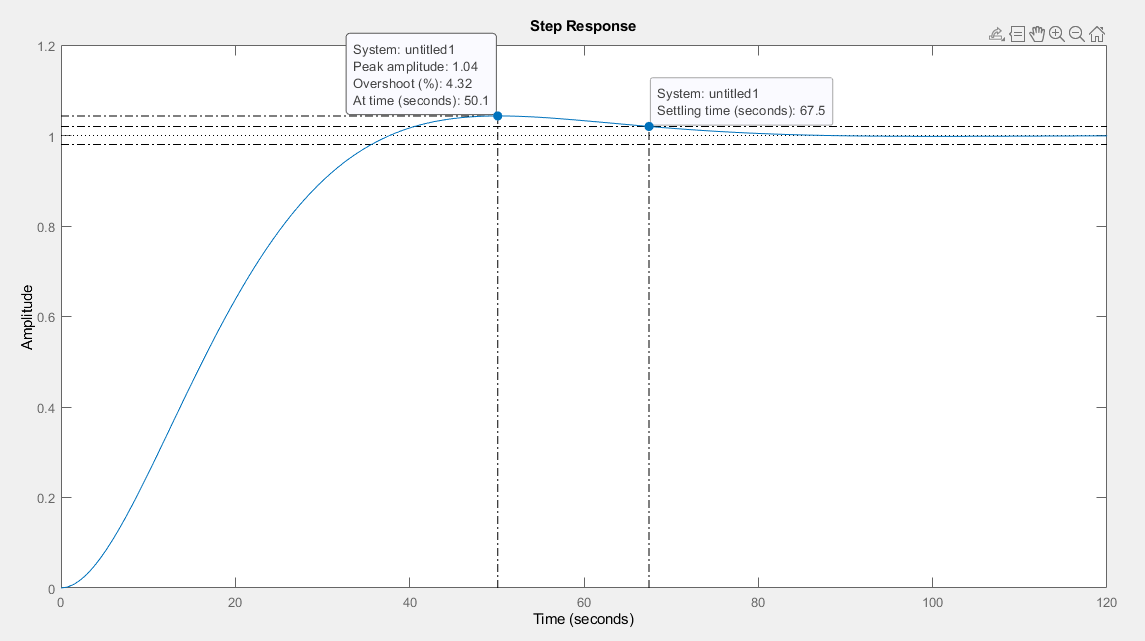

% ramp response
t = 0:1:200;
%lsim(feedback(Hr*Hf,1),t,t)

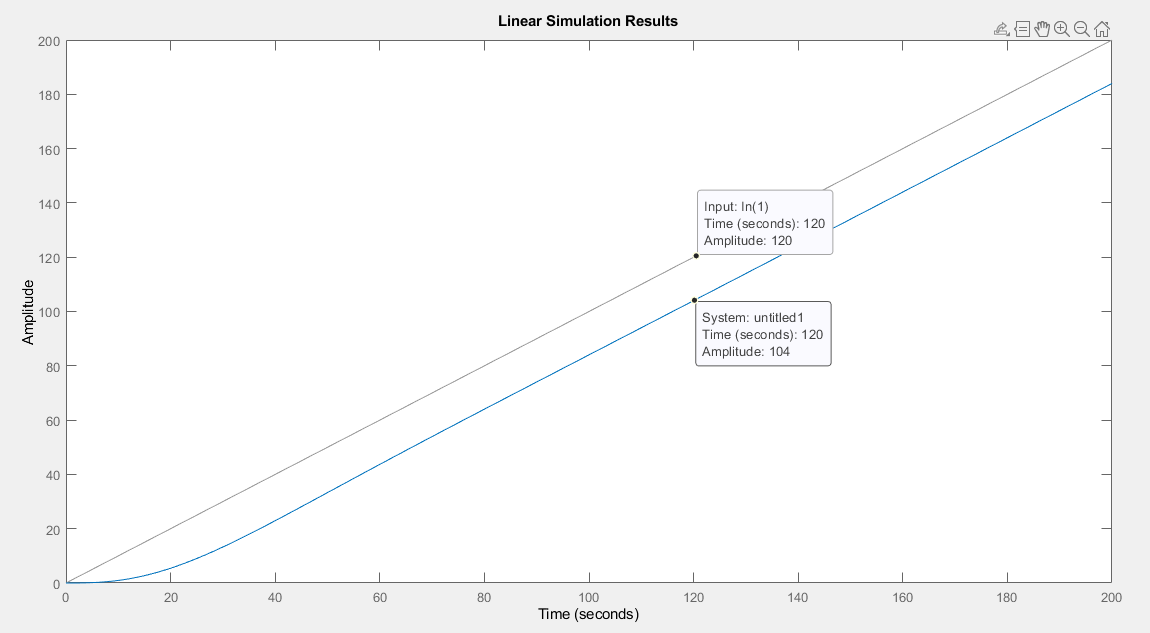

wn = 1/sqrt(2)/Tf

wn = 0.0884

zetta = 1/sqrt(2)

zetta = 0.7071

ts = 8*Tf

ts = 64

overshoot = 0.043

overshoot = 0.0430

cv = 1/2/Tf

cv = 0.0625

steadyStateError = 2*Tf

steadyStateError = 16

## Symmetry Criterion

We compute $H_d^* =\frac{4T_{\Sigma } s+1}{8T_{\Sigma }^2 s^2 \left(T_{\Sigma } s+1\right)}$

Hdstar = tf([4*Tf 1], [8*Tf^3 8*Tf^2 0 0])

Hdstar =
 
       32 s + 1
  ------------------
  4096 s^3 + 512 s^2
 
Continuous-time transfer function.



We compute $H_R =\frac{H_d^* }{H_f }$

Hr = minreal(Hdstar/Hf);
% step response
%step(feedback(Hr*Hf,1))

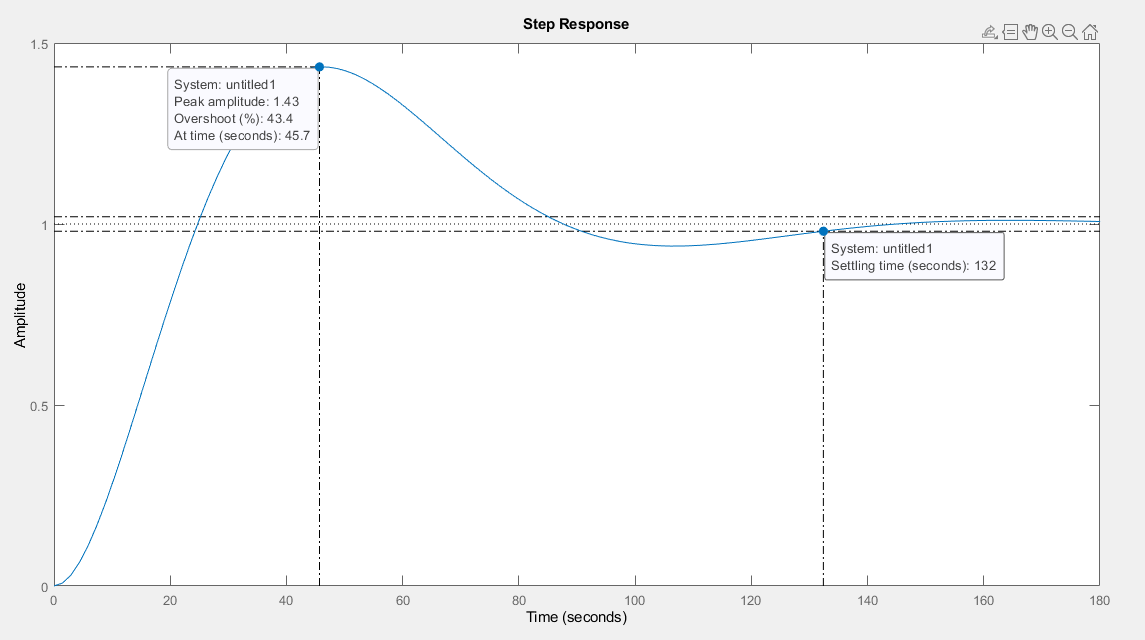

% ramp response
t = 0:1:200;
%lsim(feedback(Hr*Hf,1),t,t)